clc; clear;

Read an audio file

[x, Fs] = audioread('./audio/BeethovenOrchestra.wav');
x = x(:, 1);  % only takes one channel

Define some parameters

L = 2048;
win = hann(L);
s = 1.25;

Run any of the algorithms below

OLA

parameter.synHop = L / 4;
parameter.win = win;
parameter.tolerance = 0;
y = wsolaTSM(x, s, parameter);

WSOLA

parameter.synHop = L / 4;
parameter.win = win;
parameter.tolerance = 0;
y = wsolaTSM(x, s, parameter);

Phase Vocoder

parameter.synHop = L / 4;
parameter.win = win;
parameter.restoreEnergy = 1;
parameter.fftShift = 1;
parameter.phaseLocking = 1;
[y, sideinfo] = pvTSM(x,s,parameter);

Elastique (optional)

parameter.pitchShift = 0;
parameter.formantShift = 0;
parameter.fsAudio = Fs;
[y, sideinfo] = elastiqueTSM(x,s,parameter, {});

y =     0.0026
    0.0031
    0.0024
    0.0037
    0.0031
    0.0040
    0.0040
    0.0037
    0.0042
    0.0040


Play the output audio (optional)

obj = audioplayer(y, Fs);
play(obj);

Write the output audio (optional)

audiowrite('output.wav', y, Fs);

Evaluation based on Energy Curve

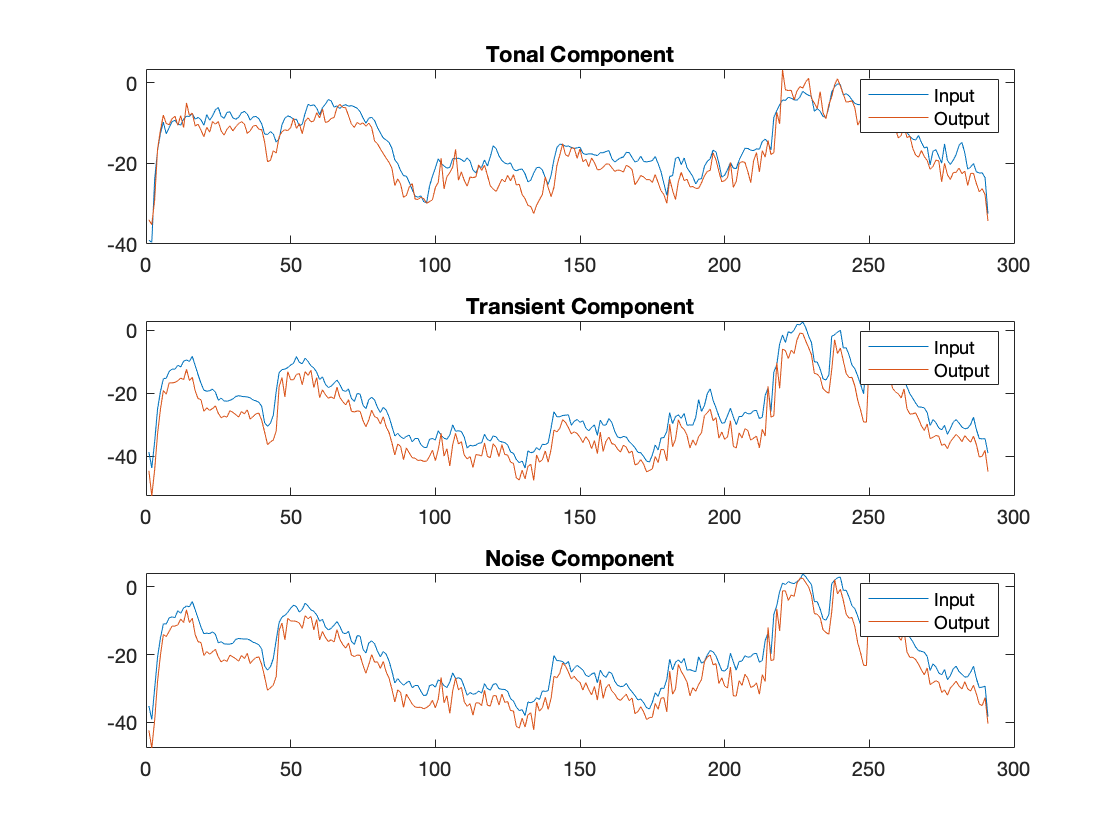

[energy_curves, energy_deviations, e] = tsmEnergyEval(x, y, L, s, Fs);

figure();
titles = {'Tonal Component', 'Transient Component', 'Noise Component'};
for i=1:length(energy_curves)/2
    subplot(length(energy_curves)/2, 1, i);
    plot(energy_curves{i*2-1});
    hold on;
    plot(energy_curves{i*2});
    hold off;
    title(titles{i});
    legend('Input', 'Output');
end

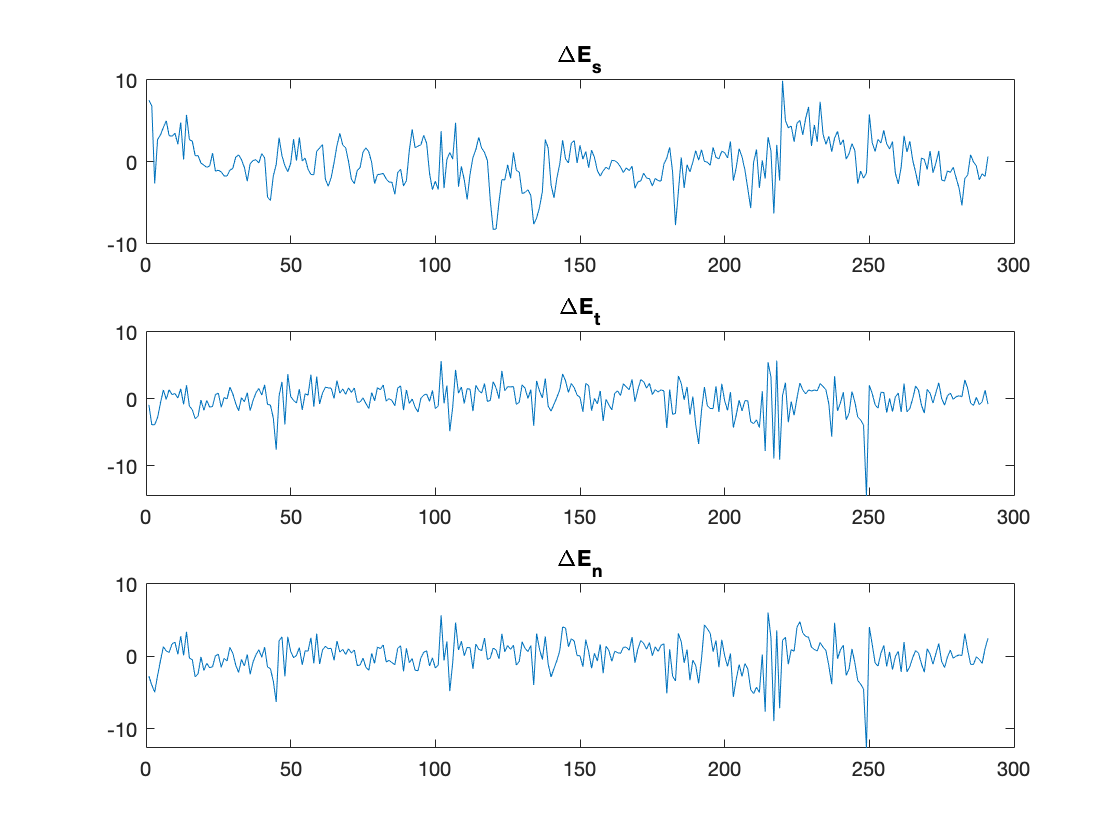


figure();
titles = {'\DeltaE_s', '\DeltaE_t', '\DeltaE_n'};
for i=1:length(energy_deviations)
    subplot(length(energy_deviations), 1, i);
    plot(energy_deviations{i});
    title(titles{i});
end